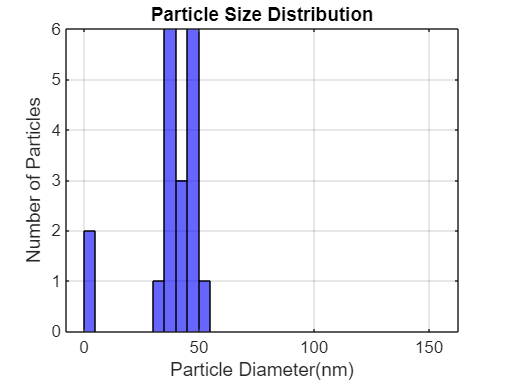

% Read the particle image
particle_image = imread('sphere.png'); % Replace 'particle_image.png' with your image file name

% Convert the image to grayscale if it's a color image
if size(particle_image, 3) == 3
    particle_image = rgb2gray(particle_image);
end

% Binarize the image using a suitable threshold
threshold = graythresh(particle_image);
bw_particle_image = imbinarize(particle_image, threshold);

% Find particle properties
stats = regionprops('table', bw_particle_image, 'Area', 'Centroid', 'MajorAxisLength', 'MinorAxisLength');

% Calculate particle diameter
particle_diameters = mean([stats.MajorAxisLength stats.MinorAxisLength], 2);

% Calculate average diameter
average_diameter = mean(particle_diameters);

% Plot bar graph of number of particles vs size
edges = 0:5:ceil(max(particle_diameters)); % Adjust the bin size as needed
histogram(particle_diameters, edges, 'FaceColor', 'blue', 'EdgeColor', 'black');
xlabel('Particle Diameter(nm)');
ylabel('Number of Particles');
title('Particle Size Distribution');
grid on;


% Count the number of particles
num_particles = size(stats, 1);
disp(['Number of particles: ', num2str(num_particles)]);

Number of particles: 20
